
clc; clear all; close all;

s=tf('s');
gp = exp(-6*s)/(s^2+0.11*s+3.01)/(s+0.99);
gptilde = exp(-6*s)/(s^2+0.1*s+3)/(s+1)

gptilde =
 
                          1
  exp(-6*s) * -------------------------
              s^3 + 1.1 s^2 + 3.1 s + 3
 
Continuous-time transfer function.
Model Properties


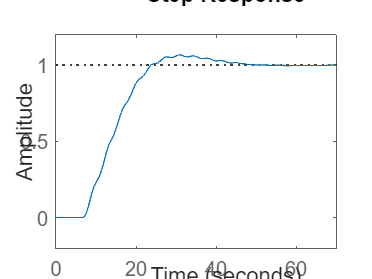

K = pidtune(gptilde,'PID'); hold on
step(feedback(K*gp,1));


INV = (s^2+0.1*s+3)*(s+1)

INV =
 
  s^3 + 1.1 s^2 + 3.1 s + 3
 
Continuous-time transfer function.
Model Properties


INV = INV/(dcgain(INV)*dcgain(gptilde));


## Gamma = 0

Lambda = 1

Lambda = 1

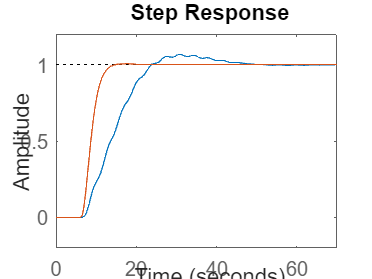

F = 1/(Lambda*s+1)^3; % n >= 0 + deg(INV) = 0+1 =1
q = INV*F;
C = q/(1-q*gptilde);
IMC_CL = feedback(C*gp,1);
step(IMC_CL);

## Gamma != 0

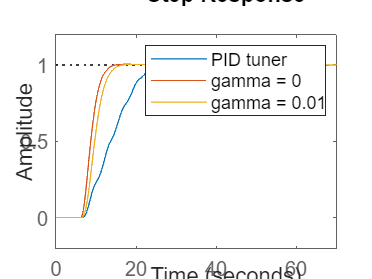

Lambda2 = 1;
gamma2 = 0.01;
F = (gamma2*s+1)/(Lambda2*s+1)^4; % n >= 1 + deg(INV) = 0+1 =1
q = INV*F;
C = q/(1-q*gptilde);
IMC_CL = feedback(C*gp,1);
step(IMC_CL);
legend('PID tuner','gamma = 0','gamma = 0.01')